CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

load('ContourData_S_EE=0.024_7D_HPC_PX1_PY1.mat','ContourData_7D') % for the base
ContourData_Base = ContourData_7D;

## All S_II slices

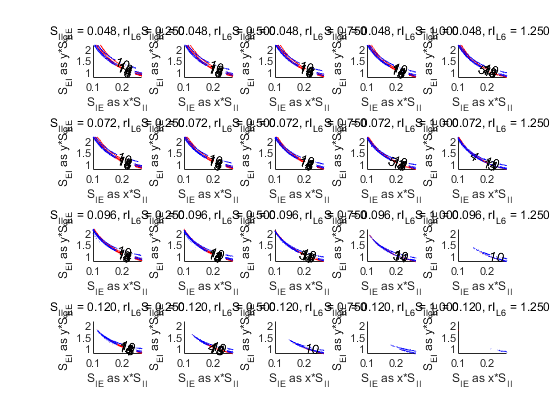

S_EEnow = ContourData_Base.S_EE;
S_IInow = ContourData_Base.S_II;
figure('Name','Contour')
for S_IlgnInd = 1:ContourData_Base.PanelNum1
    S_Ilgnnow = ContourData_Base.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_Base.PanelNum2
        rI_L6now = ContourData_Base.rI_L6test(rI_L6Ind);
        
        load(sprintf('ContourData_S_EE=0.024_7D_HPC_PX%d_PY%d.mat',S_IlgnInd,rI_L6Ind),'ContourData_7D')
        
        subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
        CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrE,[3 4 5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrI,[10 14 18],'ShowText','on','color','b');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

Check blowups

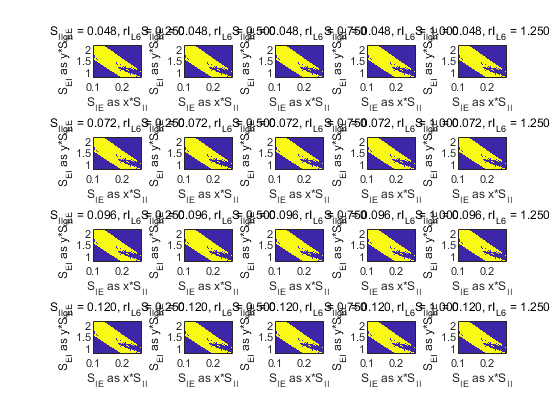

figure('Name','Failure')
SampleNum = ContourData_Base.SampleNum;
for S_IlgnInd = 1:ContourData_Base.PanelNum1
    S_Ilgnnow = ContourData_Base.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_Base.PanelNum2
        rI_L6now = ContourData_Base.rI_L6test(rI_L6Ind);
        
        load(sprintf('ContourData_S_EE=0.024_7D_HPC_PX%d_PY%d.mat',S_IlgnInd,rI_L6Ind),'ContourData_7D')
        
        subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        
        
        
        imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentBlowup);
        
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        set(gca,'Ydir','Normal')
        %xlim([0.06 0.5])
    end
end

## Firing rate heapmap

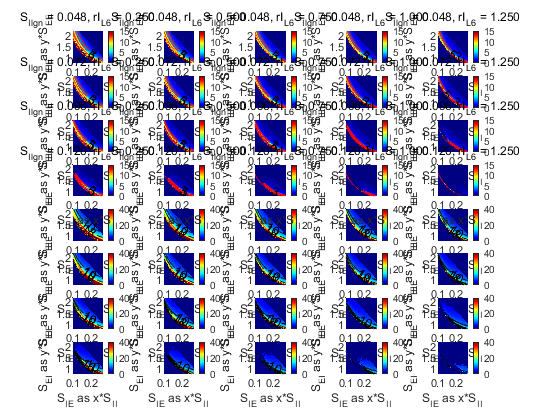

S_EEnow = ContourData_Base.S_EE;
S_IInow = ContourData_Base.S_II;
figure('Name','Heatmap')
for S_IlgnInd = 1:ContourData_Base.PanelNum1
    S_Ilgnnow = ContourData_Base.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_Base.PanelNum2
        rI_L6now = ContourData_Base.rI_L6test(rI_L6Ind);
        
        load(sprintf('ContourData_S_EE=0.024_7D_HPC_PX%d_PY%d.mat',S_IlgnInd,rI_L6Ind),'ContourData_7D')
        subplot(ContourData_Base.PanelNum1*2, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2*2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); CurrentFrE(CurrentFrE<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow, CurrentFrE)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 15])
        
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        hold off
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        
        subplot(ContourData_Base.PanelNum1*2, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1)+...
            ContourData_Base.PanelNum2 * ContourData_Base.PanelNum1)
        %     subplot(ContourData_7D.PanelNum2*2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1)+...
        %                                                                    ContourData_7D.PanelNum2 * ContourData_7D.PanelNum1)
        hold on
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: )); CurrentFrI(CurrentFrI<eps) = nan;
        imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow, CurrentFrI)
        set(gca,'YDir','normal')
        colormap("jet"); colorbar; caxis([0 40])
        [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrI,[10 18],'ShowText','on','color','k');
        clabel(C2,h2,'FontSize',10,'Color','k')
        hold off
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        %xlim([0.06 0.5])
    end
end

white frE = [3 5], frI/frE = (3, 4.25)

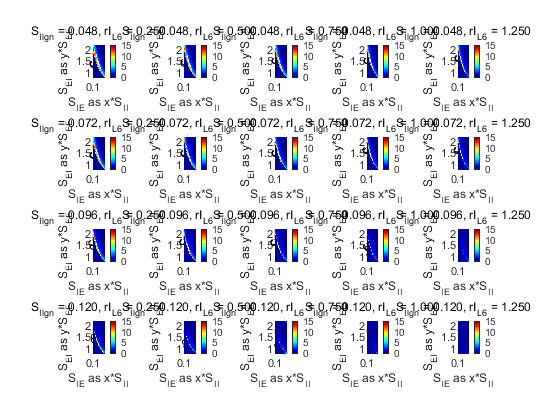

figure('Name','WhitenHeatmap')
S_EEnow = ContourData_Base.S_EE;
S_IInow = ContourData_Base.S_II;
for S_IlgnInd = 1:ContourData_Base.PanelNum1
    S_Ilgnnow = ContourData_Base.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_Base.PanelNum2
        rI_L6now = ContourData_Base.rI_L6test(rI_L6Ind);
        
        load(sprintf('ContourData_S_EE=0.024_7D_HPC_PX%d_PY%d.mat',S_IlgnInd,rI_L6Ind),'ContourData_7D')
        subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 15])
        
        
        hold off
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

And frI/frE

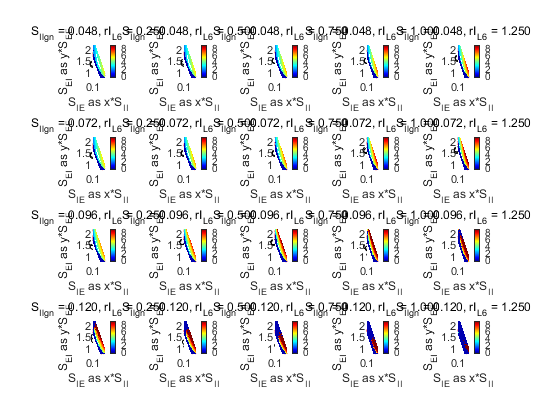

figure('Name','Fr Prop')
S_EEnow = ContourData_Base.S_EE;
S_IInow = ContourData_Base.S_II;
for S_IlgnInd = 1:ContourData_Base.PanelNum1
    S_Ilgnnow = ContourData_Base.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_Base.PanelNum2
        rI_L6now = ContourData_Base.rI_L6test(rI_L6Ind);
        
        load(sprintf('ContourData_S_EE=0.024_7D_HPC_PX%d_PY%d.mat',S_IlgnInd,rI_L6Ind),'ContourData_7D')
        subplot(ContourData_Base.PanelNum1, ContourData_Base.PanelNum2, rI_L6Ind+ContourData_Base.PanelNum2*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,  rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,: ));
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrE,[3  5 ],'ShowText','on','color','r');
        clabel(C1,h1,'FontSize',10,'Color','k')
        
        Prop = CurrentFrI./CurrentFrE;
        Prop(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        Prop(CurrentBlowup == 1) = 0;
        imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow, Prop)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(cmap); colorbar; caxis([-0.5 9])
        
        
        hold off
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    end
end

## superimpose contours

S_EEnow = ContourData_Base.S_EE;
S_IInow = ContourData_Base.S_II;
figure('Name','Contour superimpose')

for S_Ilgn trails, use this

% FirstFrE_rI_L6 = squeeze(ContourData_7D.Fr_NoFix(1,:,:,1,:));
% FirstFrI_rI_L6 = squeeze(ContourData_7D.Fr_NoFix(2,:,:,1,:));
% FirstBlowup_rI_L6 = squeeze(ContourData_7D.FailIndi(:,:,1,:));
% S_IEPush = 0.0085;

for rI_L6 trails, use this

FirstFrE_SIlgn = squeeze(ContourData_7D.Fr_NoFix(1,:,:,:,1));
FirstFrI_SIlgn = squeeze(ContourData_7D.Fr_NoFix(2,:,:,:,1));
FirstBlowup_SIlgn = squeeze(ContourData_7D.FailIndi(:,:,:,1));
S_IEPush = 0.0035; %0.007

for S_IlgnInd = 1:ContourData_7D.PanelNum1
    S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
    
    % Extract the data for the first one
    FirstBlowup = FirstBlowup_SIlgn(:,:,S_IlgnInd);
    FirstFrE = FirstFrE_SIlgn(:,:,S_IlgnInd);
    FirstFrE(FirstFrE<eps) = nan; FirstFrE(FirstBlowup == 1) = nan;
    FirstFrI = FirstFrI_SIlgn(:,:,S_IlgnInd);
    FirstFrI(FirstFrI<eps) = nan; FirstFrI(FirstBlowup == 1) = nan;
    
    for rI_L6Ind = 2:ContourData_7D.PanelNum2
        rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
        
        subplot(ContourData_7D.PanelNum1, ContourData_7D.PanelNum2-1, rI_L6Ind-1+(ContourData_7D.PanelNum2-1)*(S_IlgnInd-1))
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1-1,  rI_L6Ind-1+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:,S_IlgnInd,rI_L6Ind));
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind));
        CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind));
        CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
        [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
            CurrentFrE,[3 6 ],'ShowText','off','color','r');
        h1.DisplayName = 'FrE';
        %clabel(C1,h1,'FontSize',10,'Color','k')
        %     [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
        %                      CurrentFrI,[9 18],'ShowText','off','color','b');
        %clabel(C2,h2,'FontSize',10,'Color','k')
        
        [CF1,hF1]= contour(ContourData_7D.S_IEtest/S_IInow - (rI_L6Ind-1)*S_IEPush,ContourData_7D.S_EItest/S_EEnow,...
            FirstFrE,[3 6 ],'ShowText','off','color','m','LineStyle','--');
        hF1.LineWidth = 2;
        hF1.DisplayName = sprintf('FrE for rI_{L6}=%.3f',ContourData_7D.rI_L6test(1));
        %clabel(C1,h1,'FontSize',10,'Color','k')
        %     [CF2,hF2]= contour(ContourData_7D.S_IEtest/S_IInow - (S_IlgnInd-1)*S_IEPush,ContourData_7D.S_EItest/S_EEnow,...
        %                      FirstFrI,[9 18],'ShowText','off','color','c','LineStyle','--');
        %     hF2.LineWidth = 2;
        %clabel(C2,h2,'FontSize',10,'Color','k')
        
        hold off
        S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
        rI_L6txt = sprintf('%.3f',rI_L6now);
        title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
        xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
        legend
        %legend('FrE','FrI',sprintf('FrE for S_{Ilgn}=%.3f',ContourData_7D.S_Ilgntest(1)), sprintf('FrI for S_{Ilgn}=%.3f',ContourData_7D.S_Ilgntest(1)))
        %legend('FrE','FrI',sprintf('FrE for rI_{L6}=%.3f',ContourData_7D.rI_L6test(1)), sprintf('FrI for rI_{L6}=%.3f',ContourData_7D.rI_L6test(1)))
        %xlim([0.06 0.5])
    end
end

## parameters

sprintf(['S_EE = %.3f, S_II = %.3f, S_Elgn = %.3f, S_amb = %.3f, S_EL6 = %.3f, S_IL6 = %.3f\n',...
    'r_Elgn = %.3f, r_Ilgn = %.3f, r_Eamb = %.3f, r_Iamb = %.3f, r_EL6 = %.3f'],...
    ContourData_7D.S_EE, ContourData_7D.S_II, ContourData_7D.S_Elgn, ContourData_7D.S_amb, ContourData_7D.S_EL6, ContourData_7D.S_IL6,...
    ContourData_7D.lambda_E, ContourData_7D.lambda_I, ContourData_7D.rE_amb, ContourData_7D.rI_amb, ContourData_7D.rE_L6)


## Check single contourmap

S_IlgnInd = 5; rI_L6Ind = 2;
S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrE(CurrentFrE<eps) = nan;
CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrI(CurrentFrI<eps) = nan;
figure('Name','Check Single Contour')
subplot 121
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrE)
set(gca,'Ydir','Normal')
CurrentFrE(CurrentFrE<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
    CurrentFrE,[3  5 ],'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 8])
title('frE Contour')

subplot 122
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrI)
set(gca,'Ydir','Normal')
CurrentFrI(CurrentFrI<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
    CurrentFrI,[10  18 ],'ShowText','on','color','b');
clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 24])
title('frI Contour')

S_IEInd = 6; S_EIInd = 15;
Fr_TrajInterest = ContourData_7D.Fr_NoFixTraj{S_EIInd,S_IEInd,S_IlgnInd,rI_L6Ind};
mV_TrajInterest = ContourData_7D.mV_NoFixTraj{S_EIInd,S_IEInd,S_IlgnInd,rI_L6Ind};
figure('Name','Traj')
plot(Fr_TrajInterest(1,:))
hold on
plot(Fr_TrajInterest(2,:))


## new test

%unpackStruct(ContourData_7D)

S_IlgnInd = 5; rI_L6Ind = 2;
%S_IEInd = 6; S_EIInd = 4;

S_EItest = ContourData_7D.S_EItest;
S_IEtest = ContourData_7D.S_IEtest;

S_EIGridSz = S_EItest(2)-S_EItest(1);
S_IEGridSz = S_IEtest(2)-S_IEtest(1);

SimuT = 40000;
GridRatio = 0.0;

% MeanFieldEst_BkGd_Indep_StepSize_ref_testL6
% MeanFieldEst_BkGd_ref_L6_testNegIpt
[a,b,c,d,e] = MeanFieldEst_BkGd_Indep_StepSize_ref_testL6(ContourData_7D.C_EE,ContourData_7D.C_EI,ContourData_7D.C_IE,ContourData_7D.C_II,...
    ContourData_7D.S_EE,...
    ContourData_7D.S_EItest(S_EIInd),...
    ContourData_7D.S_IEtest(S_IEInd)+GridRatio*S_IEGridSz,...
    ContourData_7D.S_II,ContourData_7D.p_EEFail,...
    ContourData_7D.lambda_E,ContourData_7D.S_Elgn,ContourData_7D.rE_amb,ContourData_7D.S_amb,...
    ContourData_7D.lambda_I,ContourData_7D.S_Ilgntest(S_IlgnInd),ContourData_7D.rI_amb,...
    ContourData_7D.S_EL6,ContourData_7D.S_IL6,ContourData_7D.rE_L6,ContourData_7D.rI_L6test(rI_L6Ind),...
    ContourData_7D.tau_ampa_R,ContourData_7D.tau_ampa_D,ContourData_7D.tau_nmda_R,ContourData_7D.tau_nmda_D,...
    ContourData_7D.tau_gaba_R,ContourData_7D.tau_gaba_D,ContourData_7D.tau_ref,...
    ContourData_7D.rhoE_ampa,ContourData_7D.rhoE_nmda,ContourData_7D.rhoI_ampa,ContourData_7D.rhoI_nmda,...
    ContourData_7D.gL_E,ContourData_7D.gL_I,ContourData_7D.Ve,ContourData_7D.Vi,...
    ContourData_7D.N_HC,ContourData_7D.n_E_HC,ContourData_7D.n_I_HC,...
    'End',ContourData_7D.SampleNum,ContourData_7D.StopNum,ContourData_7D.h,SimuT);

figure('Name','testTraj')
hold on
plot(a(1,:))
plot(a(2,:))
title(sprintf('S_{EI}/S_{EE} = %.3f; S_{IE}/S_{II} = %.3f',...
    ContourData_7D.S_EItest(S_EIInd)/ContourData_7D.S_EE,...
    (ContourData_7D.S_IEtest(S_IEInd)+GridRatio*S_IEGridSz)/ContourData_7D.S_II ))